nDims = 100;
nDims_informative = 5;
m0 = zeros(nDims,1);
m1 = zeros(nDims,1);
m1(1:nDims_informative) = 3;
ds_train = prtDataGenUnimodal(51,m0,m1,eye(nDims),eye(nDims));
ds_test = prtDataGenUnimodal(51,m0,m1,eye(nDims),eye(nDims));

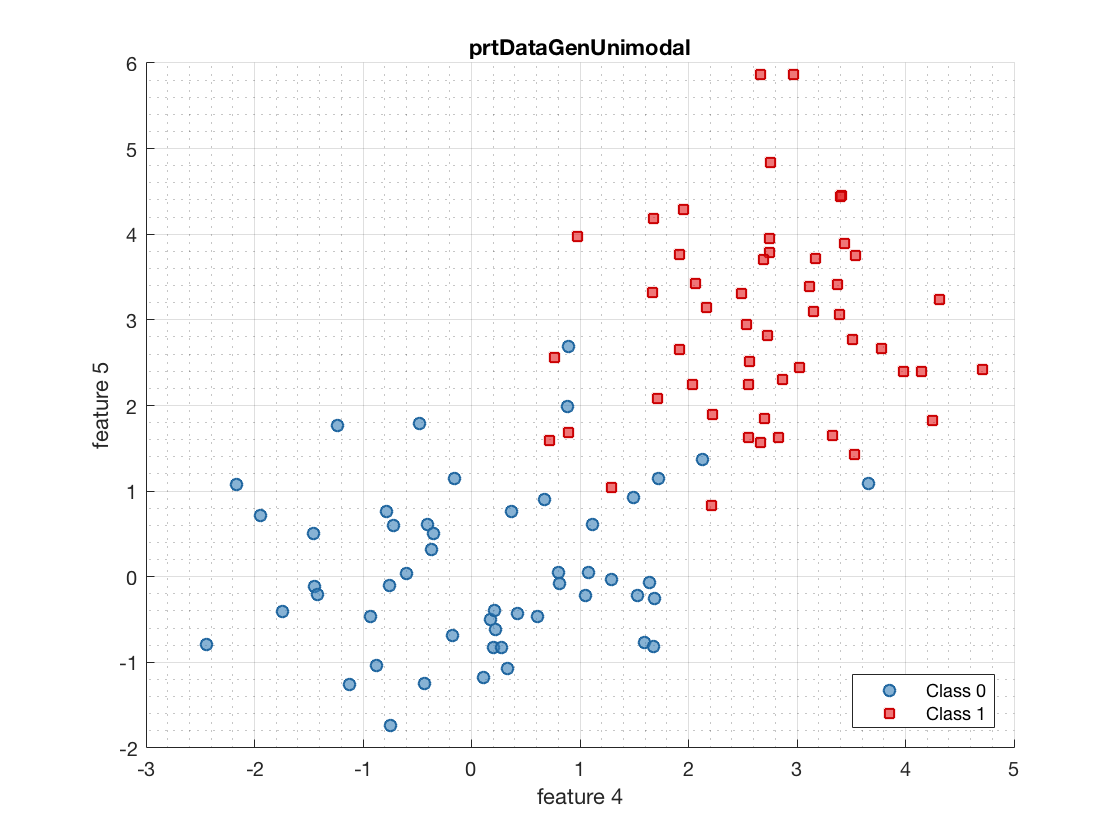

plot(ds_train.retainFeatures(4:5))
xlabel('feature 4')
ylabel('feature 5')

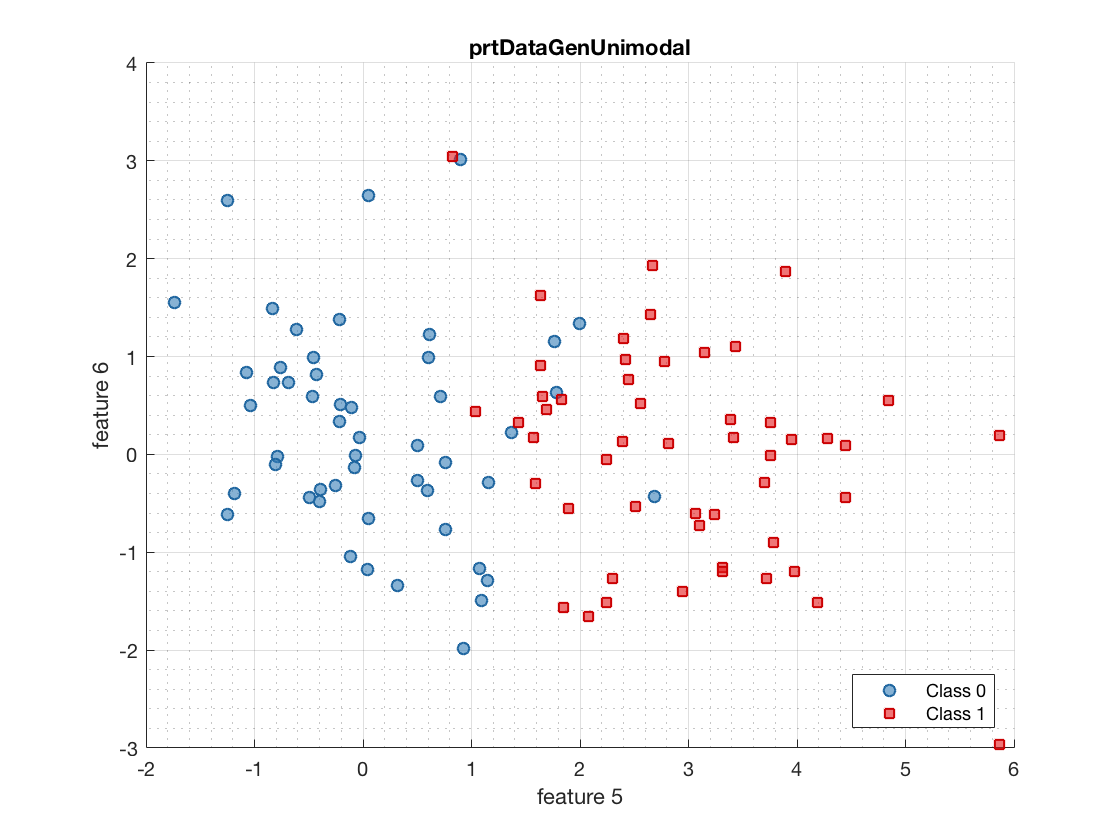

plot(ds_train.retainFeatures(5:6))
xlabel('feature 5')
ylabel('feature 6')

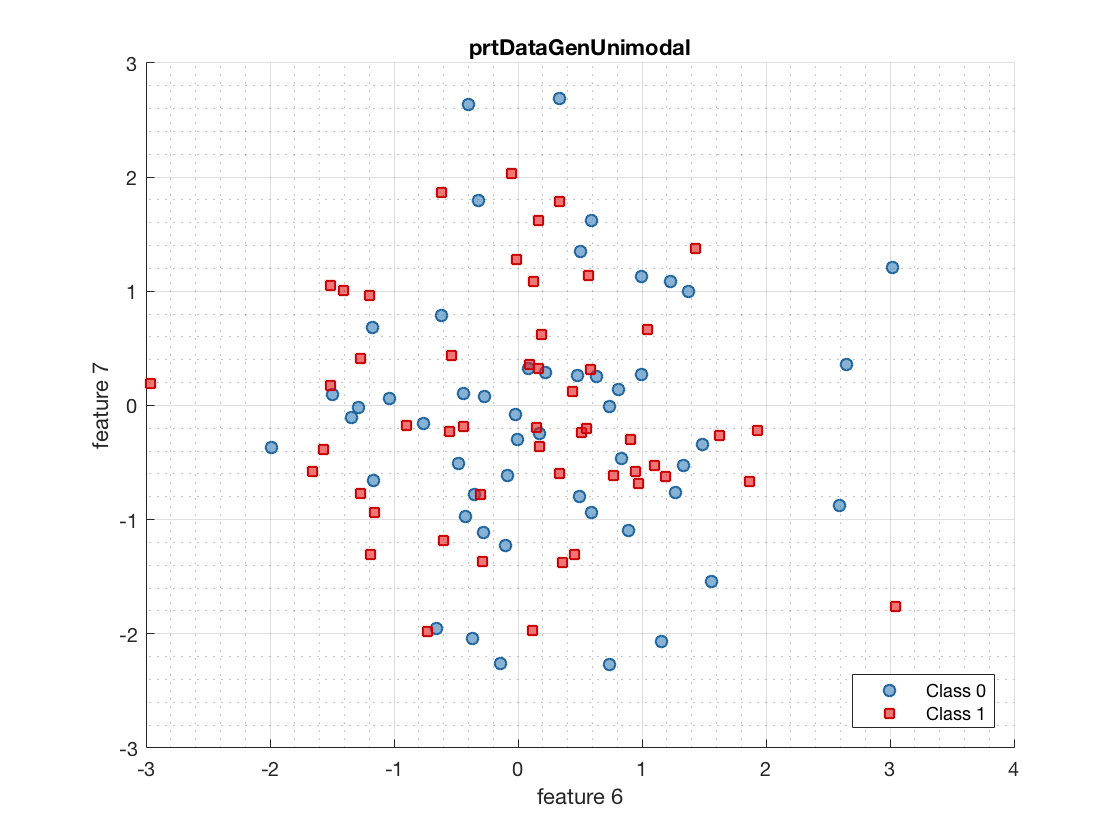

plot(ds_train.retainFeatures(6:7))
xlabel('feature 6')
ylabel('feature 7')

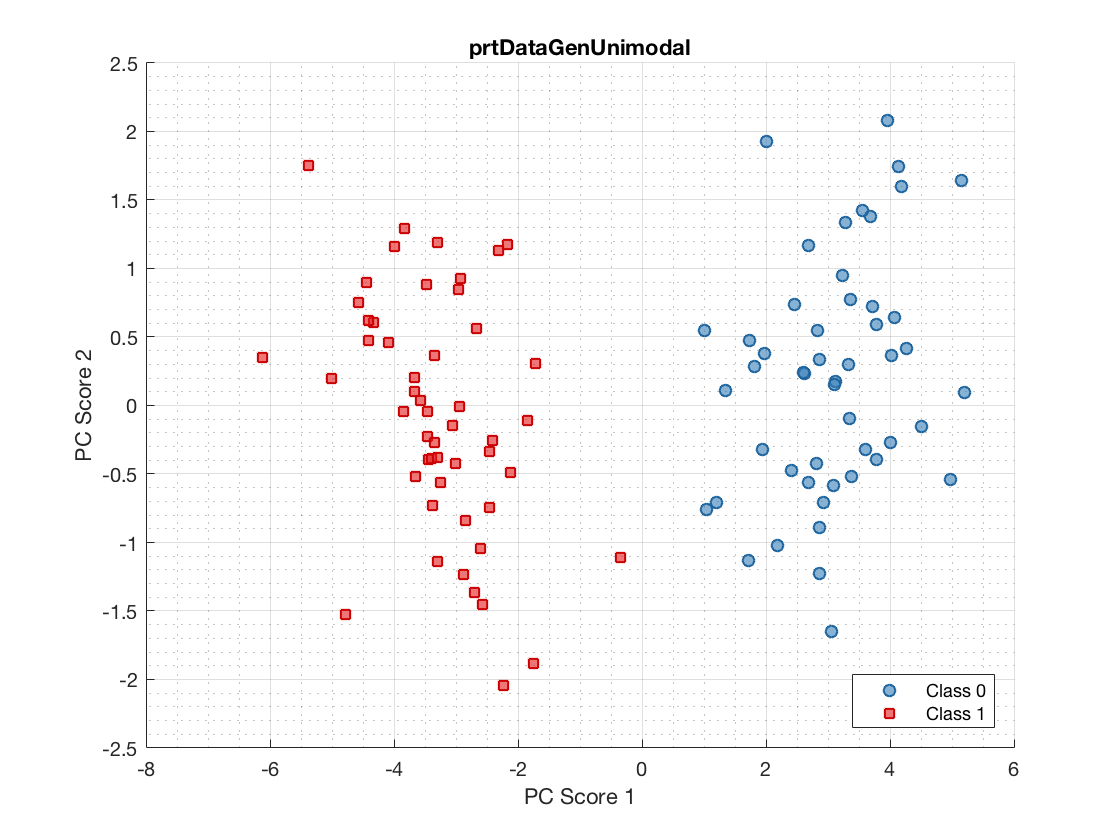

pca = prtPreProcPca('nComponents',2);
pca_trained = pca.train(ds_train);
plot(pca_trained.run(ds_test))

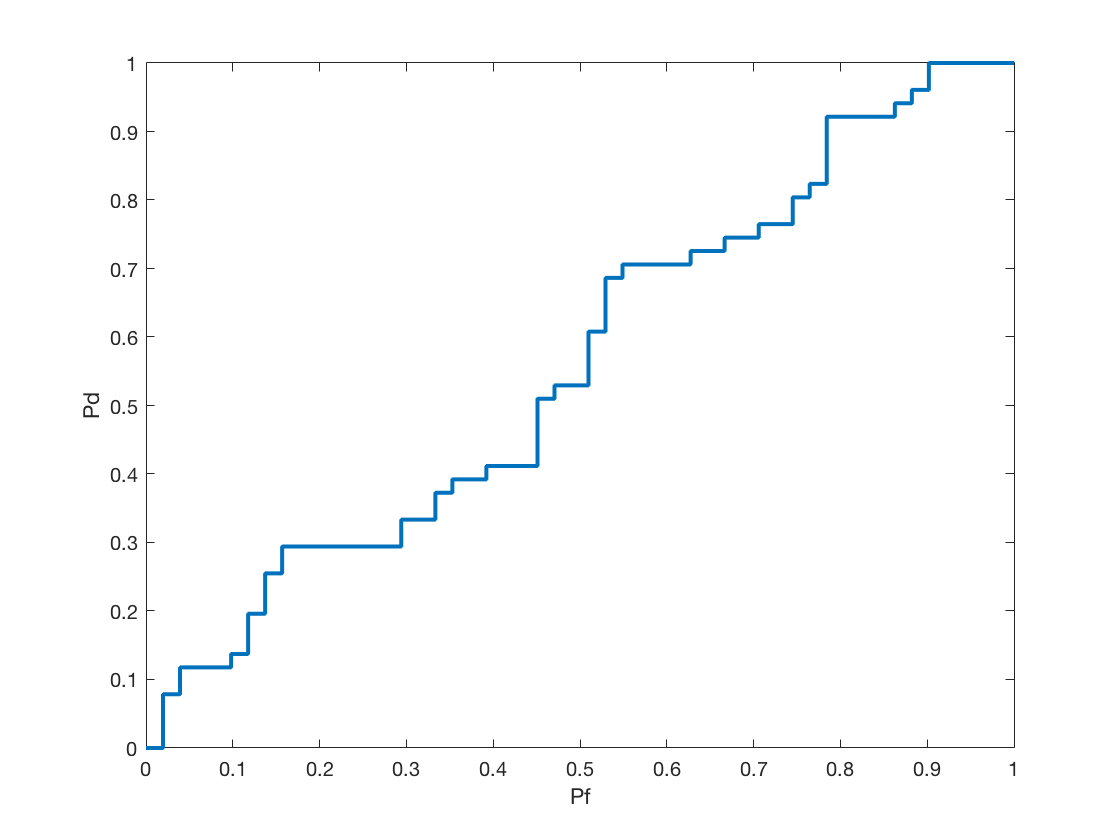

cls = prtClassFld;
cls_trained = cls.train(ds_train);
prtScoreRoc(cls_trained.run(ds_test))

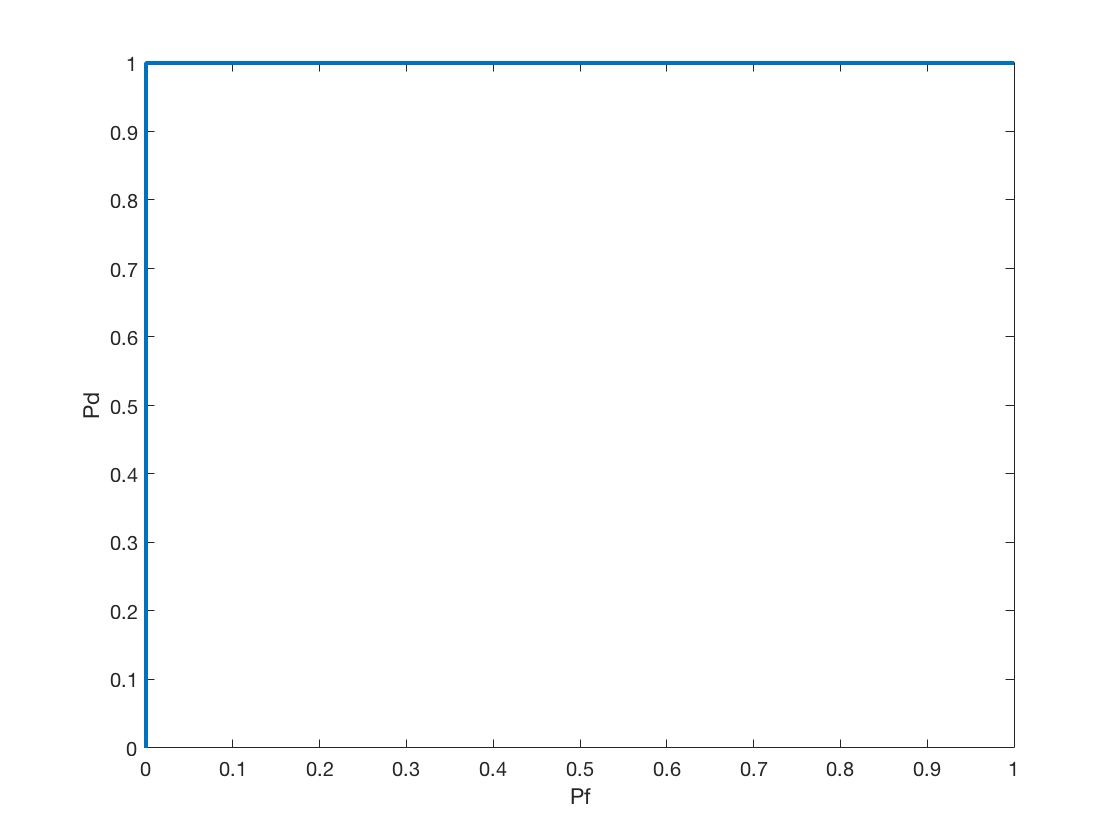

cls = prtPreProcPca('nComponents',2) + prtClassFld;
cls_trained = cls.train(ds_train);
prtScoreRoc(cls_trained.run(ds_test))

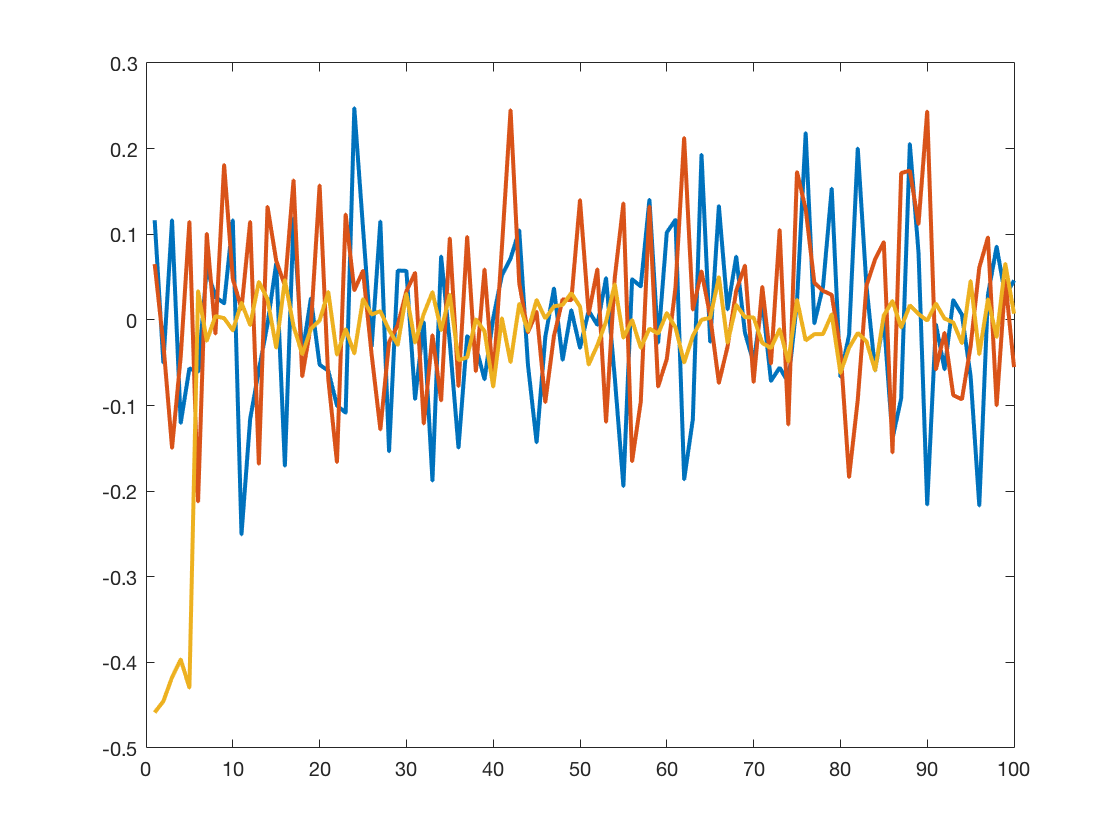

Sigma = cov(ds_train.X);
[vec,val] = eig(Sigma);
plot(vec(:,end-2:end))